# Solar Panel Output Estimator

Specify the location of your panels.

% Calculate Solar Time
location = [42.35 -71.0589 -5];
[lambda, phi, UTCoff, TZ, localYear, localMonth, localDay, beta, tau, pRad] = solTime(location);


Specify the panel size and efficiency value.

% Calculate Panel Size and Efficiency
pSize = 27;                          % Panel size in m^2
eff = 46;                         % Panel efficiency
pElec = eff*pSize*pRad;                                    % Panel electric output in kW
 

### Results: 

disp(['Expected electrical output = ' num2str(pElec) ' kW'])

Expected electrical output = 1116.3994 kW


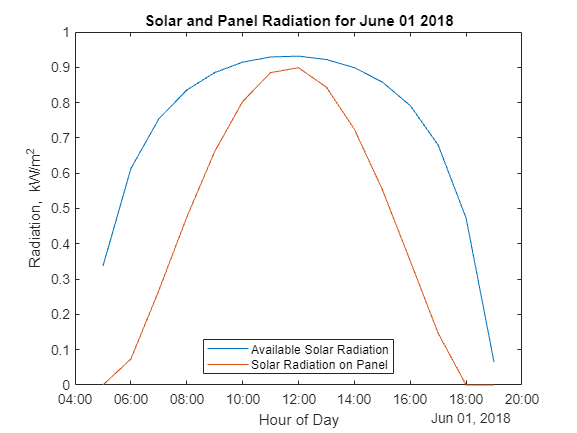


% Calculate Power Generation Over Time
isFixed = 1;
date = datetime(localYear,localMonth,localDay,'TimeZone',TZ);                      
[times, sRad, pRad] = hourlyPanelRadiation(date, lambda, phi, UTCoff, tau, beta, isFixed) ;

plot(times,sRad,times,pRad)
title(['Solar and Panel Radiation for ' datestr(date,'mmmm dd yyyy')])
xlabel('Hour of Day');
ylabel('Radiation, kW/m^2')
legend('Available Solar Radiation','Solar Radiation on Panel', 'Location','South')

** To view the code for this example, go to the ****View**** tab and click ****Output on Right**** or ****Output Inline****.*

*Copyright 2019 The MathWorks, Inc.*